## Project 1 Mutual Information

### Step 1 读取数据

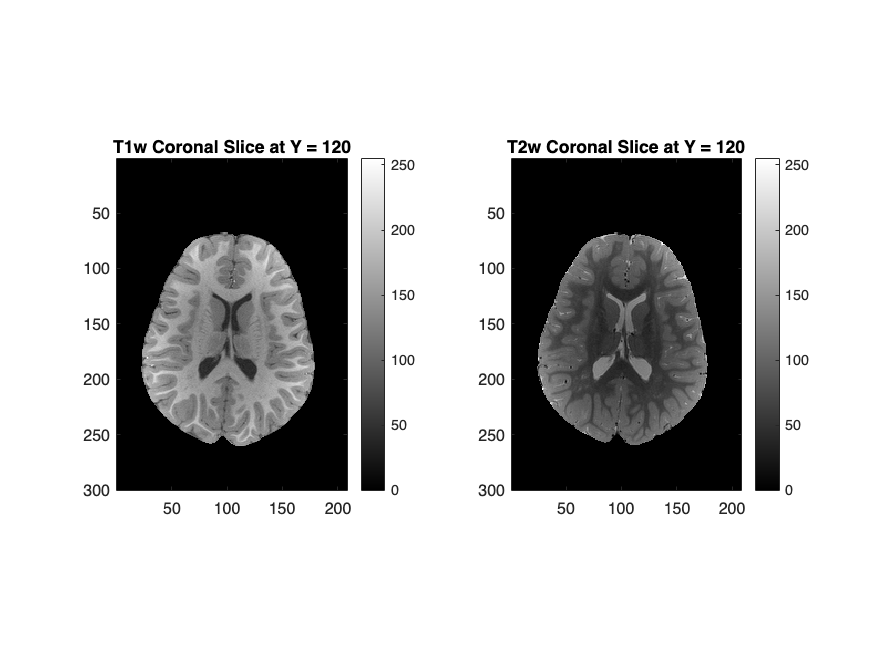

% 读取 NIfTI 图像
t1 = niftiread('dataset/T1w.nii');
t2 = niftiread('dataset/T2w.nii');

% 手动设置你想看的冠状切片高度（Y轴索引）
y_index = 120;

% 提取冠状切片（固定Y轴）
slice_t1 = squeeze(t1(:, y_index, :));
slice_t2 = squeeze(t2(:, y_index, :));

% 归一化到 0~255 并转为 uint8
slice_t1_norm = uint8(255 * mat2gray(slice_t1));
slice_t2_norm = uint8(255 * mat2gray(slice_t2));

% 显示图像（保留坐标、灰度条）
figure;

subplot(1,2,1);
imagesc(slice_t1_norm);
axis image;
colormap(gray);
colorbar;
title(['T1w Coronal Slice at Y = ', num2str(y_index)]);

subplot(1,2,2);
imagesc(slice_t2_norm);
axis image;
colormap(gray);
colorbar;
title(['T2w Coronal Slice at Y = ', num2str(y_index)]);

### Step 2 计算联合直方图

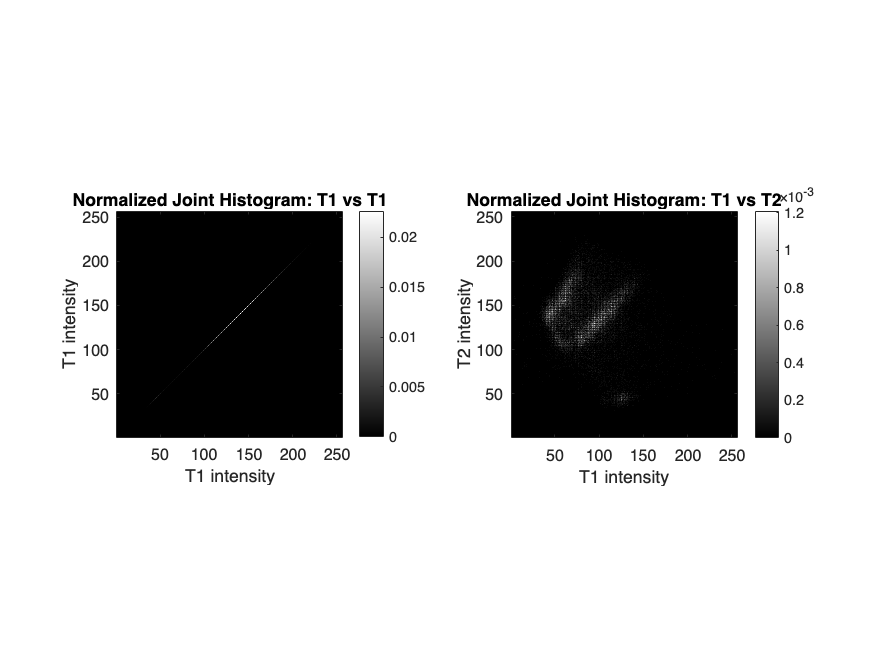

function jointHist = computeJointHist(v1, v2, nbins)
    % 输入：
    % v1, v2: 灰度向量，范围应是0~255整数
    % nbins: 直方图bin数量（256）
    
    % 过滤掉(0,0)对
    valid_idx = ~(v1 == 0 & v2 == 0);
    v1 = v1(valid_idx);
    v2 = v2(valid_idx);
    
    % 初始化联合直方图矩阵
    jointHist = zeros(nbins, nbins);
    
    % 遍历所有像素对，统计落在哪个bin
    % 假设灰度已经是整数0~255，bin索引就是值+1
    for k = 1:length(v1)
        i = v1(k) + 1;
        j = v2(k) + 1;
        jointHist(i,j) = jointHist(i,j) + 1;
    end
end

v1 = double(slice_t1_norm(:));
v2 = double(slice_t2_norm(:));
nbins = 256;

jointHist_t1_t1 = computeJointHist(v1, v1, nbins);
jointHist_t1_t2 = computeJointHist(v1, v2, nbins);

jointProb_t1_t1 = jointHist_t1_t1 / sum(jointHist_t1_t1(:));
jointProb_t1_t2 = jointHist_t1_t2 / sum(jointHist_t1_t2(:));

% 显示
figure;

subplot(1,2,1);
imagesc(jointProb_t1_t1);
axis image; colormap gray; colorbar;
set(gca, 'YDir', 'normal');  % Y轴从下往上
title('Normalized Joint Histogram: T1 vs T1');
xlabel('T1 intensity');
ylabel('T1 intensity');

subplot(1,2,2);
imagesc(jointProb_t1_t2);
axis image; colormap gray; colorbar;
set(gca, 'YDir', 'normal');  % Y轴从下往上
title('Normalized Joint Histogram: T1 vs T2');
xlabel('T1 intensity');
ylabel('T2 intensity');

### Step 3 计算互信息

function MI = computeMutualInformation(jointProb)
    % 计算两个图像的互信息（Mutual Information）
    % 输入 jointProb：已经归一化的联合概率矩阵（256x256）

    % 计算边缘分布
    pA = sum(jointProb, 2); % 每行求和，图像 A 的边缘概率
    pB = sum(jointProb, 1); % 每列求和，图像 B 的边缘概率

    % 初始化互信息
    MI = 0;

    % 遍历每个元素
    for i = 1:size(jointProb, 1)
        for j = 1:size(jointProb, 2)
            p_ij = jointProb(i, j);
            if p_ij > 0
                MI = MI + p_ij * log2(p_ij / (pA(i) * pB(j)));
            end
        end
    end
end

jointProb_t1_t1 = jointHist_t1_t1 / sum(jointHist_t1_t1(:));
jointProb_t1_t2 = jointHist_t1_t2 / sum(jointHist_t1_t2(:));

% 计算互信息
MI_t1_t1 = computeMutualInformation(jointProb_t1_t1);
MI_t1_t2 = computeMutualInformation(jointProb_t1_t2);

% 显示结果
fprintf('Mutual Information between T1 and T1: %.4f\n', MI_t1_t1);

Mutual Information between T1 and T1: 6.8091


fprintf('Mutual Information between T1 and T2: %.4f\n', MI_t1_t2);

Mutual Information between T1 and T2: 0.9794
